# **Data processing, No. 1 borehole in Jintan City**

close all
clc
clear
warning off
format long

## Data format (important!), Sort by filed test project

- nzsensing DTS_+Tstart+_+Tend+.mat or Ultima DTS_+Tstart+_+Tend+.mat; Save it as basic data

- Test information = Info.mat

- Data in borehole and the certain time = Test+number1+Process+number2.timeseconds/temperarure/anti-temperature/depth/anti-depth.mat; number1 = the number of test in one field project; number2 = 1/2, 1 = time parting, and 2 = depth parting

- Thermal response test in borehole and the certain time = Heat + the contents in (3)

- Natural temperarture in borehole and the certain time = Natural + the contents in (3)

- Data tranform in Natural temperature in our database (jintan.mat). jintan.bore+borehole number+.depth+yyyymmdd = NaturalProcess2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2);

- Thermal conducivity results. TC.begin_t+number*, TC.finish_t+number*, number* is the serial number of thermal response test; TC.value+number*, number* is the serial number of thermal response test

- Save above data (every field project). jintan.bore+borehole number+.depth+yyyymmdd = Natural+number1+Process+number2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2)

- Data tranform in Thermal Conductivity in our database (jintan.mat). jintan.bore+borehole number+.thermalConductivity+yyyymmdd= TC.value

## Fileld Project-202207

### Temperature observation; Nzsensing DTS

#### 1 Load data

[fname,pathn] = uigetfile('*.txt','请选择文件','MultiSelect','on');
fname = cellstr(fname);
[m,n] = size(fname);
filename = char(fname(1,1));
[data,textdata] = importdata([pathn,filename]);

y=length(fname);
startTime=cell(1,y);
for j=1:y
    t=fname(1,j);
    t1=char(t);
    T=t1(4:18);
    T=strrep(T,'_',' ');
    T=[T(1:4),'/',T(5:6),'/',T(7:11),':',T(12:13),':',T(14:end)];%
    Time(:,j)=cellstr(T);
end
startTime = datetime(Time,'InputFormat','yyyy/MM/dd HH:mm:ss');


[m1,~] = size(data.data(:,1));
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    [m2,~] = size(data.data(:,1));
    if m2 < m1
       m1 = m2;
    end
end
txt_data = zeros(m1,n);
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    TMP(:,j) = data.data(1:m1,3);
end

LAF = data.data(1:m1,2);

DTS.startTime=startTime;
DTS.LAF=LAF;
DTS.TMP=TMP;

Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['nzsensing DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/07/30  13:00:00'; % apply the test
Info.end_test = '2022/07/30  14:30:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');
% 202207Borehole [37.4,144.66,251.92]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=37.4 && DTS.LAF(k,1)<=144.66
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-37.4;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=144.66 && DTS.LAF(k,1)<=251.92
        q = q+1;
        Test1Process2.anti_depth(q,1) = 251.92-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);

clear k q

#### Chech the results

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,289),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore1.depth20220730 = Test1Process2.depth;
changzhou.bore1.temperature202207301345 = mean(Test1Process2.temperature(:,1:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_01_20220730_process_202301091555.mat

#### 8 Next one

clear 
clc

## Fileld Project-202209

### Temperature observation; Nzsensing  DTS

#### 1 Load data

[fname,pathn] = uigetfile('*.txt','请选择文件','MultiSelect','on');
fname = cellstr(fname);
[m,n] = size(fname);
filename = char(fname(1,1));
[data,textdata] = importdata([pathn,filename]);

y=length(fname);
startTime=cell(1,y);
for j=1:y
    t=fname(1,j);
    t1=char(t);
    T=t1(4:18);
    T=strrep(T,'_',' ');
    T=[T(1:4),'/',T(5:6),'/',T(7:11),':',T(12:13),':',T(14:end)];%
    Time(:,j)=cellstr(T);
end
startTime = datetime(Time,'InputFormat','yyyy/MM/dd HH:mm:ss');


[m1,~] = size(data.data(:,1));
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    [m2,~] = size(data.data(:,1));
    if m2 < m1
       m1 = m2;
    end
end
txt_data = zeros(m1,n);
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    TMP(:,j) = data.data(1:m1,3);
end

LAF = data.data(1:m1,2);

DTS.startTime=startTime;
DTS.LAF=LAF;
DTS.TMP=TMP;

Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['nzsensing DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/09/26  17:40:00'; % apply the test
Info.end_test = '2022/09/26  19:20:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([15 30])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');
% 202207Borehole [36.99,144.25,251.51)

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=36.99 && DTS.LAF(k,1)<=144.625
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-36.99;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=144.625 && DTS.LAF(k,1)<=251.51
        q = q+1;
        Test1Process2.anti_depth(q,1) = 251.51-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);

clear k q

#### Check the results

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,289),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore1.depth20220926 = Test1Process2.depth;
changzhou.bore1.temperature202209261825 = mean(Test1Process2.temperature(:,1:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_01_20220926_process_202301091608.mat

#### 8 Next one

clear 
clc

## Fileld Project-202211

### Temperature observation; Nzsensing DTS

#### 1 Load data

[fname,pathn] = uigetfile('*.txt','请选择文件','MultiSelect','on');
fname = cellstr(fname);
[m,n] = size(fname);
filename = char(fname(1,1));
[data,textdata] = importdata([pathn,filename]);

y=length(fname);
startTime=cell(1,y);
for j=1:y
    t=fname(1,j);
    t1=char(t);
    T=t1(4:18);
    T=strrep(T,'_',' ');
    T=[T(1:4),'/',T(5:6),'/',T(7:11),':',T(12:13),':',T(14:end)];%
    Time(:,j)=cellstr(T);
end
startTime = datetime(Time,'InputFormat','yyyy/MM/dd HH:mm:ss');


[m1,~] = size(data.data(:,1));
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    [m2,~] = size(data.data(:,1));
    if m2 < m1
       m1 = m2;
    end
end
txt_data = zeros(m1,n);
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    TMP(:,j) = data.data(1:m1,3);
end

LAF = data.data(1:m1,2);

DTS.startTime=startTime;
DTS.LAF=LAF;
DTS.TMP=TMP;

Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['nzsensing DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/11/24  22:00:00'; % apply the test
Info.end_test = '2022/11/24  22:30:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

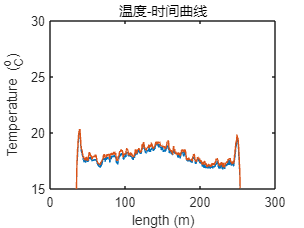

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([15 30])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');

% 202207Borehole [37.4,144.25,251.1)

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=37.4 && DTS.LAF(k,1)<=144.25
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-37.4;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=144.25 && DTS.LAF(k,1)<=251.1
        q = q+1;
        Test1Process2.anti_depth(q,1) = 251.1-DTS.LAF(k,1);
        Test1Process2.anti_temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

Test1Process2.anti_depth = flip(Test1Process2.anti_depth);
Test1Process2.anti_temperature = flip(Test1Process2.anti_temperature);

clear k q

#### Check the results

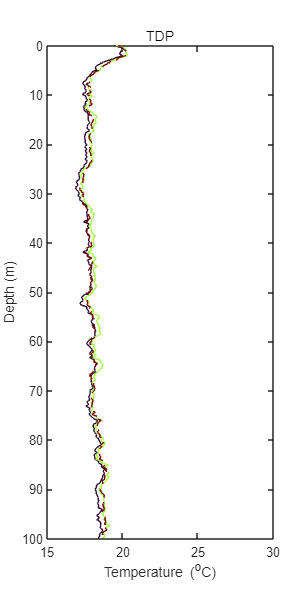

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,25),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);

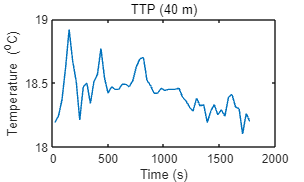

clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore1.depth20221124 = Test1Process2.depth;
changzhou.bore1.temperature202211242214 = mean(Test1Process2.temperature(:,1:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_01_20221124_process_202301092318.mat

#### 8 Next one

clear 
clc